## Pre-process data

### Create folders for saving data for training, validation and testing.

**If these folders exist with old data, please delete them before proceeding. Take a backup if desired.**

if ~exist('train','dir') 
    mkdir train 
end
if ~exist('val','dir') 
    mkdir val 
end
if ~exist('test','dir') 
    mkdir test 
end

### Pre-process Training data

Load training data (X_train). **Ensure that childmind_data folder is added to path.**

load child_mind_x_train_2s_24chan_raw.mat

% number of training samples (each sample = 24 x 256 size)
% num_train = size(X_train,3);

Load training labels (Y_train) which contains 4 columns: Subject_ID,  Sex (1 = Female, 0 = Male), Age, EHQ_Total (+100 = Fully Right-Handed, -100 = Fully Left-Handed)

load child_mind_all_labels_train_2s_24chan_raw.mat

Convert the .mat training samples to .tif images

cd train;
train_label_info = mat2tiff(X_train,Y_train,'s3://childminddata/train')

train_label_info = 71138×6 string array
    "s3://childminddata/train/NDARFB908HVX/sample_1.tif"     "NDARFB908HVX"    "0"    "8.2563"    <missing>    "1" 
    "s3://childminddata/train/NDARFB908HVX/sample_2.tif"     "NDARFB908HVX"    "0"    "8.2563"    <missing>    "2" 
    "s3://childminddata/train/NDARFB908HVX/sample_3.tif"     "NDARFB908HVX"    "0"    "8.2563"    <missing>    "3" 
    "s3://childminddata/train/NDARFB908HVX/sample_4.tif"     "NDARFB908HVX"    "0"    "8.2563"    <missing>    "4" 
    "s3://childminddata/train/NDARFB908HVX/sample_5.tif"     "NDARFB908HVX"    "0"    "8.2563"    <missing>    "5" 
    "s3://childminddata/train/NDARFB908HVX/sample_6.tif"     "NDARFB908HVX"    "0"    "8.2563"    <missing>    "6" 
    "s3://childminddata/train/NDARFB908HVX/sample_7.tif"     "NDARFB908HVX"    "0"    "8.2563"    <missing>    "7" 
    "s3://childminddata/train/NDARFB908HVX/sample_8.tif"     "NDARFB908HVX"    "0"    "8.2563"    <missing>    "8" 
    "s3://childminddata/train/ND

cd ..

Sort the labels for correct indexing of the labels when creating a datastore. **Change the 'WriteMode' to 'append' if you want to retain the previous contents of the file.**

train_label_sorted = sortrows(train_label_info,2);
writematrix(train_label_sorted,'childmind_train_labels_s3.txt','Delimiter','tab','WriteMode','overwrite');

### Pre-process Validation data

Load validation data (X_val). **Ensure that childmind_data folder is added to path.**


load child_mind_x_val_2s_24chan_raw.mat 


Load validation labels (Y_val).

load child_mind_all_labels_val_2s_24chan_raw.mat 


Convert validation samples to .tif images

cd val;
val_label_info = mat2tiff(X_val,Y_val,'s3://childminddata/val')

val_label_info = 39641×6 string array
    "s3://childminddata/val/NDARBL242L4H/sample_1.tif"     "NDARBL242L4H"    "0"    "10.4379"    "94.51"    "1" 
    "s3://childminddata/val/NDARBL242L4H/sample_2.tif"     "NDARBL242L4H"    "0"    "10.4379"    "94.51"    "2" 
    "s3://childminddata/val/NDARBL242L4H/sample_3.tif"     "NDARBL242L4H"    "0"    "10.4379"    "94.51"    "3" 
    "s3://childminddata/val/NDARBL242L4H/sample_4.tif"     "NDARBL242L4H"    "0"    "10.4379"    "94.51"    "4" 
    "s3://childminddata/val/NDARBL242L4H/sample_5.tif"     "NDARBL242L4H"    "0"    "10.4379"    "94.51"    "5" 
    "s3://childminddata/val/NDARBL242L4H/sample_6.tif"     "NDARBL242L4H"    "0"    "10.4379"    "94.51"    "6" 
    "s3://childminddata/val/NDARBL242L4H/sample_7.tif"     "NDARBL242L4H"    "0"    "10.4379"    "94.51"    "7" 
    "s3://childminddata/val/NDARBL242L4H/sample_8.tif"     "NDARBL242L4H"    "0"    "10.4379"    "94.51"    "8" 
    "s3://childminddata/val/NDARBL242L4H/sample_9.tif"    

cd ..

Sort the labels for correct indexing of the labels when creating a datastore. **Change the 'WriteMode' to 'append' if you want to retain the previous contents of the file.**

val_label_sorted = sortrows(val_label_info,2);
writematrix(val_label_sorted,'childmind_val_labels_s3.txt','Delimiter','tab','WriteMode','overwrite');

### Pre-process Test data

Load training data (X_test). **Ensure that childmind_data folder is added to path.**

load child_mind_x_test_2s_24chan_raw.mat


Load training labels (Y_test)

load child_mind_all_labels_test_2s_24chan_raw.mat

Convert test samples to tif files

cd test
test_label_info = mat2tiff(X_test,Y_test,'s3://childminddata/test')
cd ..

Sort the labels for correct indexing of the labels when creating a datastore. **Change the 'WriteMode' to 'append' if you want to retain the previous contents of the file.**

test_label_sorted = sortrows(test_label_info,2);
writematrix(test_label_sorted,'childmind_test_labels_s3.txt','Delimiter','tab','WriteMode','overwrite');

## Creating Datastores

### For local datastore

Create training imageDatastore

train_imds = imageDatastore('train',"IncludeSubfolders",true,"FileExtensions",".tif");

Create validation datastore

val_imds = imageDatastore('val',"IncludeSubfolders",true,"FileExtensions",".tif");

Create test datastore

test_imds = imageDatastore('test',"IncludeSubfolders",true,"FileExtensions",".tif");

### For AWS s3 bucket 

**Run this section only after the data has been uploaded to the s3 bucket**

% Uncomment the following code for anonymous access to the dataset
% setenv('AWS_ACCESS_KEY_ID','');
% setenv('AWS_SECRET_ACCESS_KEY','')

% train_imds = imageDatastore('s3://childminddata/train',"IncludeSubfolders",true,"FileExtensions",".tif");
% 
% val_imds = imageDatastore('s3://childminddata/val',"IncludeSubfolders",true,"FileExtensions",".tif");
% 
% test_imds = imageDatastore('s3://childminddata/test',"IncludeSubfolders",true,"FileExtensions",".tif");


## Choose which label you want

1: Subject_ID  

2: Sex (1 = Female, 0 = Male)

3: Age

4: EHQ_Total (+100 = Fully Right-Handed, -100 = Fully Left-Handed)

NB- 5: is just the 2s sample number for a given subject

label_col = 2; %change this to choose a different label. 

**NB: If you choose a label that isn't a categorical vector, training will not run. Also, if you choose a column other than 2, the output size of te last layer of the R-VGG network must be changed to match the number of categories in the training set (to be implemented).**

### Read labels locally

train_imds.Labels = train_label_sorted(:,label_col+1);
val_imds.Labels = val_label_sorted(:,label_col+1);
test_imds.Labels = test_label_sorted(:,label_col+1);

### Alternatively: Read labels from a text file 

This will work only after a text file has already been created. Note that the labels of an ImageDatastore must be a categorical vector.

fid = fopen('childmind_train_labels_s3.txt','r');
train_label_data = textscan(fid, '%s\t%s\t%d\t%n\t%n\t%d');
fclose(fid);
train_imds.Labels = categorical(train_label_data{1,label_col+1});


fid = fopen('childmind_val_labels_s3.txt','r');
val_label_data = textscan(fid, '%s\t%s\t%d\t%n\t%n\t%d');
fclose(fid);
val_imds.Labels = categorical(val_label_data{1,label_col+1});


fid = fopen('childmind_test_labels_s3.txt','r');
test_label_data = textscan(fid, '%s\t%s\t%d\t%n\t%n\t%d');
fclose(fid);
test_imds.Labels = categorical(test_label_data{1,label_col+1});

## Load the network layers to be trained

load('R-VGG_noNormalization.mat')
%deepNetworkDesigner

## Training the network

Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'MaxEpochs',2, ...
    'MiniBatchSize',70, ...
    'Plots','training-progress',...
    'ValidationData',val_imds);

Train the network

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:09 |       54.29% |       50.14% |       1.3916 |       5.2053 |          0.0005 |
|       1 |          50 |       00:02:24 |       57.14% |       57.98% |       0.6920 |       0.7452 |          0.0005 |
|       1 |         100 |       00:03:36 |       62.86% |       54.81% |       0.6597 |       0.7036 |          0.0005 |
|       1 |         150 |       00:04:50 |       75.71% |       64.99% |       0.5844 |       0.6921 |          0.0005 |
|       

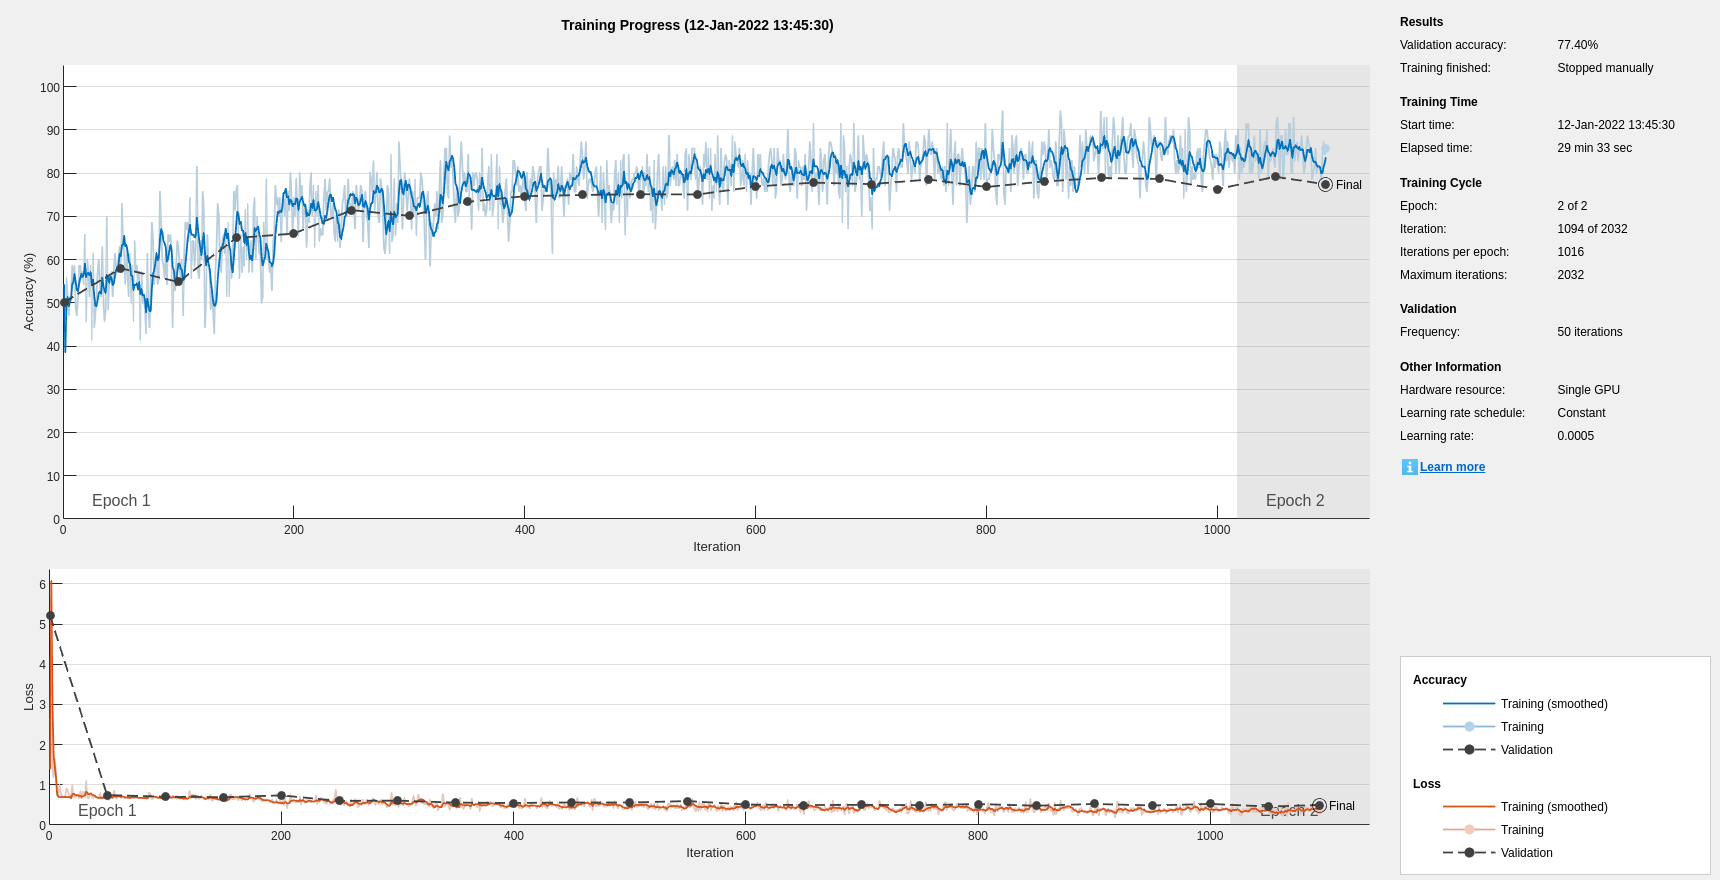

tiff_net = trainNetwork(train_imds,layers,options);

## Testing the trained network

Y_pred = classify(tiff_net,test_imds);

num_test = length(Y_pred);
%Test accuracy
correct = 0;
for i = 1 : num_test
    if(Y_pred(i)==test_imds.Labels(i))
        correct = correct+1;
    end
end

test_accuracy = 100*correct/num_test

test_accuracy = 78.7190